# 1D Muscle Model based on the **Hill** 2-Element Model

clear all

## Model Overview

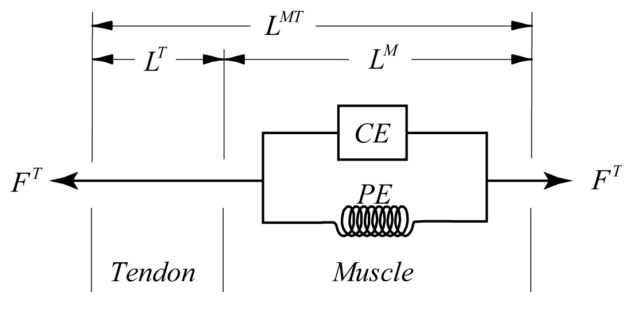

Schematic taken from \cite{Anderson2007}999.

Global plotting options

fnum = 1;
opt_grid = 'on';
opt_hold =  'off';
splotx = 0;
sploty = 0;

## Global muscle properties

$L_{rest}$ is the muscle resting length, $P_{max}$ is the maximum force the muscle can produce and $v_{max}$ is the maximum velocity of shortening.

L_REST = 0.5; %mm
F_MAX = 5; %N
V_MAX = 1.5; %mm/s

$a$ and $b$ are shape constants for the muscle force-velocity relationship

% muscle model constants
a = 0.25;
b = a*V_MAX/F_MAX;

## Parallel elastic element

This element represents the passive response of the muscle upon streching greater than resting length.

Note that $L_{PE}=L_{TOT}=L_{CE}$

The form of the passive relationship is not easily found in literature and is implemented in a straight forward way here to match the requirements of an exponential form which is non-zero above $L_{rest}$;


$$F_{PE} = F_{MAX}c \times [e^{L_{TOT}/L{REST}-1}-1]$$


Parameter $c$ is introduced to tune the shape of the curve. 

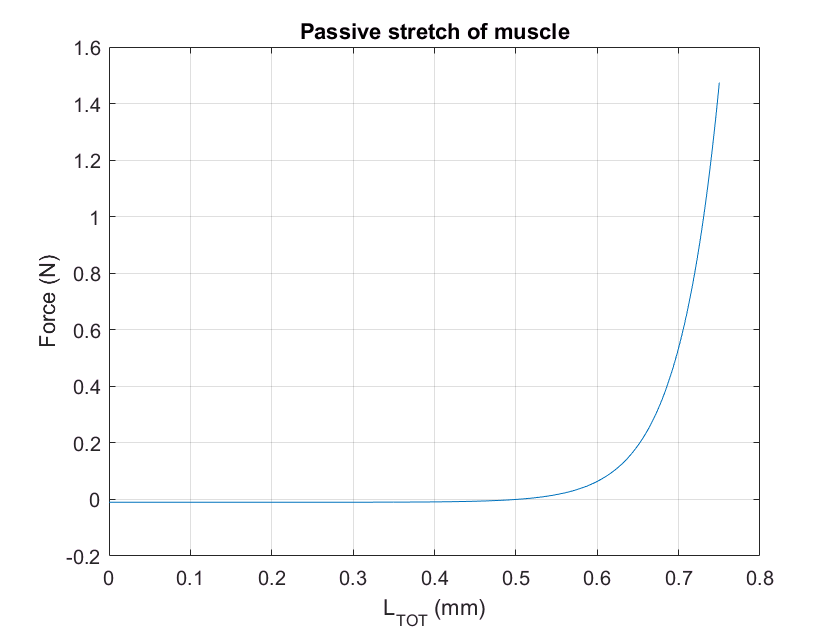

L_TOT = (0:0.001:L_REST*1.5);
F_PE = parallel_elastic(L_TOT, L_REST, F_MAX);

xvec = L_TOT;
yvec = F_PE;
ftitle = 'Passive stretch of muscle';
xtitle = 'L_{TOT} (mm)';
ytitle = 'Force (N)';
plotxy(xvec, yvec, fnum, ftitle, xtitle, ytitle, opt_grid, opt_hold, ...
    splotx, sploty)

## Contractile element

This element is reponsible for the active force production in the muscle. The total force is given in the form;


$$F_{CE} = \alpha(t) \times F_{vel}(V)\times F_{len}(L_{TOT})$$


As a first step, we assume that the muscle is fully tetanized, i.e. $\alpha(t)  = 1$. 

Force-velocity

Taken from \cite{Challis1994a}999, based on \cite{Hill1938}999.


$$F_{VEL} = \frac{a(V_{MAX}-V)}{(b-V)}$$


where $a$ and $b$ have been fit to $V_{MAX}$ and $F_{MAX}$.

V = 0:0.01:1.1*V_MAX;
F_VEL = force_vel(V_MAX, V, F_MAX,a ,b)

F_VEL =     1.0000    0.8765    0.7789    0.7000    0.6348    0.5800    0.5333    0.4931    0.4581    0.4273    0.4000    0.3757    0.3538    0.3341    0.3163    0.3000    0.2851    0.2714    0.2588    0.2472    0.2364    0.2263    0.2169    0.2082    0.2000    0.1923    0.1851    0.1783    0.1718    0.1658    0.1600    0.1545    0.1494    0.1444    0.1398    0.1353    0.1310    0.1270    0.1231    0.1194    0.1158    0.1124    0.1091    0.1059    0.1029    0.1000    0.0972    0.0945    0.0919    0.0894


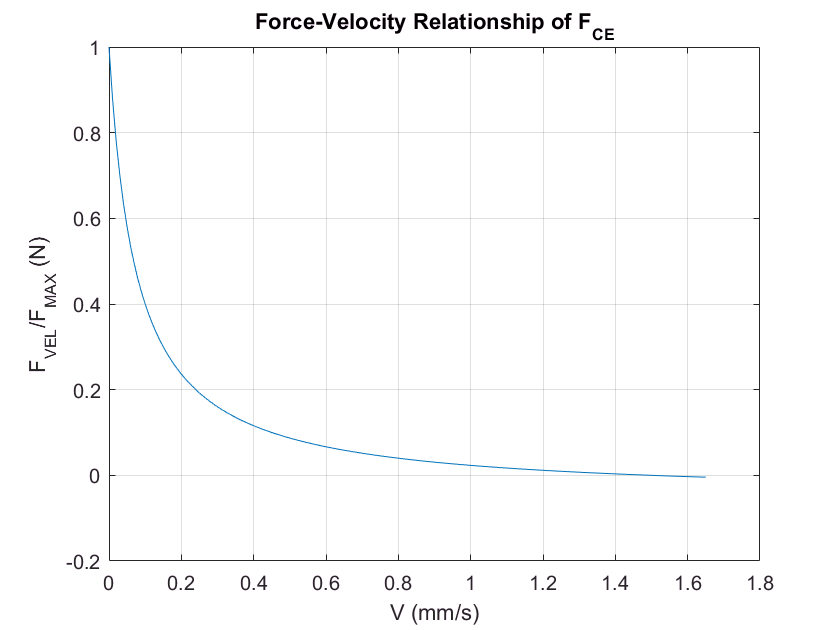


xvec = V;
yvec = F_VEL;
ftitle = 'Force-Velocity Relationship of F_{CE}';
xtitle = 'V (mm/s)';
ytitle = 'F_{VEL}/F_{MAX} (N)';
plotxy(xvec, yvec, fnum, ftitle, xtitle, ytitle, opt_grid, opt_hold, ...
    splotx, sploty)

Force-Length

Taken from \cite{Challis1994a}999, based on \cite{Hatze1981}999;


$$F_{LEN}=F_{MAX}[e^{-(\frac{Q-1}{SK})^2}]$$


where $Q = L_{CE}/L_{REST}$ and$SK$ is a material parameter.

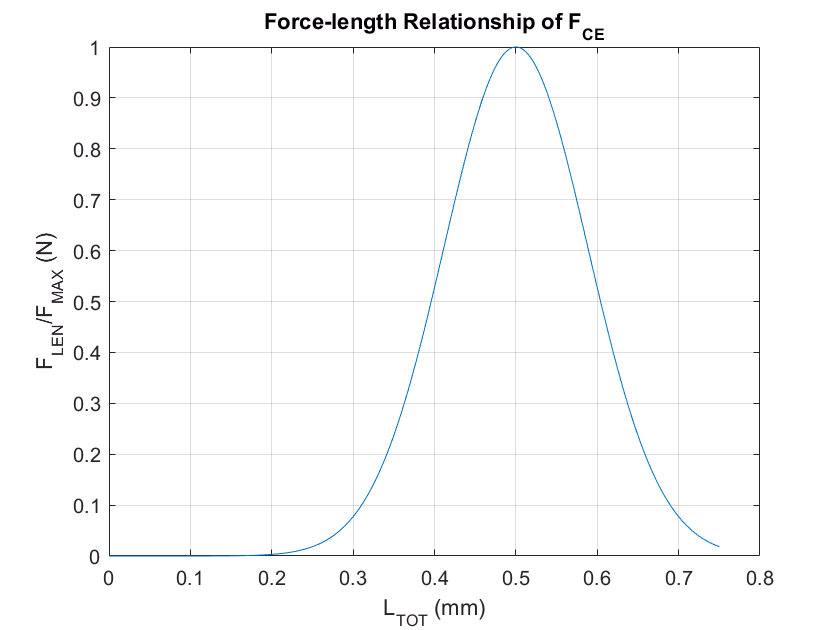

F_LEN = force_length(L_TOT, L_REST, F_MAX);

xvec = L_TOT;
yvec = F_LEN;
ftitle = 'Force-length Relationship of F_{CE}';
xtitle = 'L_{TOT} (mm)';
ytitle = 'F_{LEN}/F_{MAX} (N)';
plotxy(xvec, yvec, fnum, ftitle, xtitle, ytitle, opt_grid, opt_hold, ...
    splotx, sploty)

Now, returning to the contractile elment total force (normalising the indiviual relatioships to maximum force); 


$$F_{CE} = F_{MAX} \times \frac{a(V_{MAX}-V)}{(b-V)F_{MAX}} \times e^{-(\frac{L_{CE}/L_{REST}-1}{SK})^2}$$


recall that the muscle is currently fully tetanised. 

## Total muscle force

Total force of the muscle is given by summing the passive and active parts; 


$$F_{MUSC} = F_{CE}+F_{PE}$$



$$F_{MUSC} =  F_{MAX} \times \{ \frac{a(V_{MAX}-V)}{(b-V)F_{MAX}} \times 
e^{-(\frac{L_{CE}/L_{REST}-1}{SK})^2} + c[e^{L_{TOT}/L{REST}-1}-1] \}$$


Constant velocity

Now, consider the muscle shortening at a constant velocity.

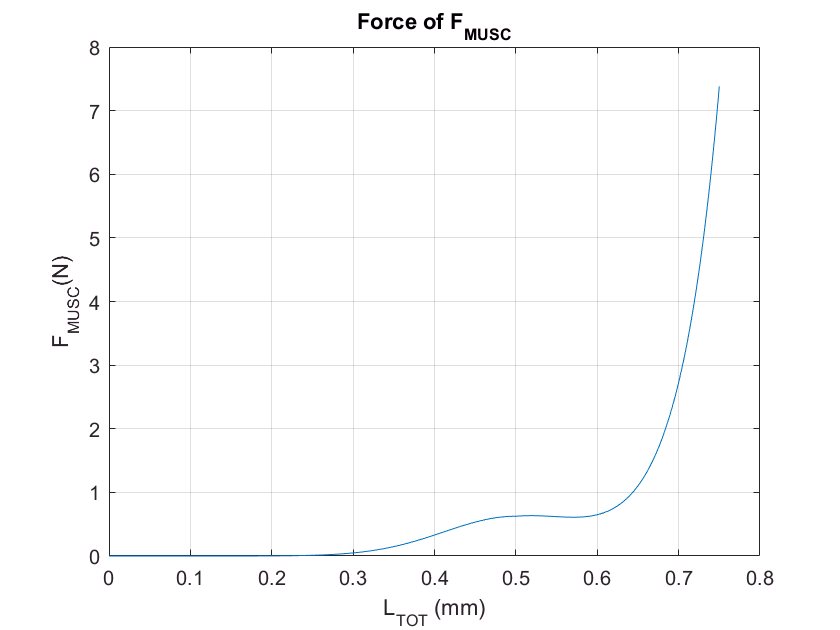

% activation
alpha = 1;
% loading velocity
V = 0.25*V_MAX;
F_MUSC = force_muscle(L_TOT, L_REST, V_MAX, V, a, b, F_MAX, alpha);

xvec = L_TOT;
yvec = F_MUSC;
ftitle = 'Force of F_{MUSC}';
xtitle = 'L_{TOT} (mm)';
ytitle = 'F_{MUSC}(N)';
opt_hold = 'off';
plotxy(xvec, yvec, fnum, ftitle, xtitle, ytitle, opt_grid, opt_hold, ...
    splotx, sploty)

External Loading 

Now, consider an external loading as follows:

- Stretch the muscle passively to some intiial length: $L_{INIT}$

- Activate the muscle to some activity level: $\alpha_{FIXED}$ (for now, consider full activation) to give an initial (isometric) force: $F_{INIT}$

- Find the (local) stiffness at this point: $K_{INIT}^{MUSC}=F_{INIT}/L_{INIT}$

- Free one end of the muscle and instantly apply an external load: $F_{EXT}$

- Use the stiffness to find the resulting muscle length: $L_ {FIN} = F_{EXT}/K_{INIT}^{MUSC}$

- If $F_{EXT}$ > $F_{INIT}$ - eccentric contraction

- If $F_{EXT}$ < $F_{INIT}$ - concentric contraction

L_INIT = 0.5; 
% Isometric case & full activation
V = 0; 
alpha = 1;
% At full activation
F_INIT = force_muscle(L_INIT,L_REST,V_MAX,V, a, b, F_MAX, alpha)

F_INIT = 5

% local stiffness
K_INIT = F_INIT/L_INIT %N/mm

K_INIT = 10

% apply external load for eccentric loading
F_EXT = 6;
% find final length of activated muscle
L_FIN = F_EXT/K_INIT

L_FIN = 0.6000

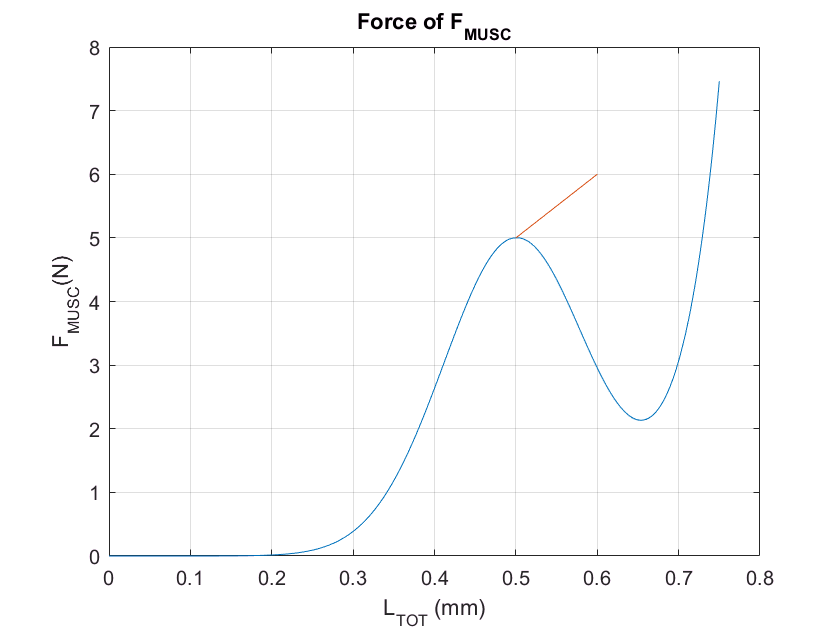

MUSC_DEF(1,:) = [L_INIT, F_INIT];
MUSC_DEF(2,:) = [L_FIN, F_EXT];

F_MUSC = force_muscle(L_TOT,L_REST,V_MAX,V, a, b, F_MAX, alpha);
xvec = L_TOT;
yvec = F_MUSC;
ftitle = 'Force of F_{MUSC}';
xtitle = 'L_{TOT} (mm)';
ytitle = 'F_{MUSC}(N)';
opt_hold = 'on';
plotxy(xvec, yvec, fnum, ftitle, xtitle, ytitle, opt_grid, opt_hold, ...
    splotx, sploty)
plot(MUSC_DEF(:,1),MUSC_DEF(:,2));